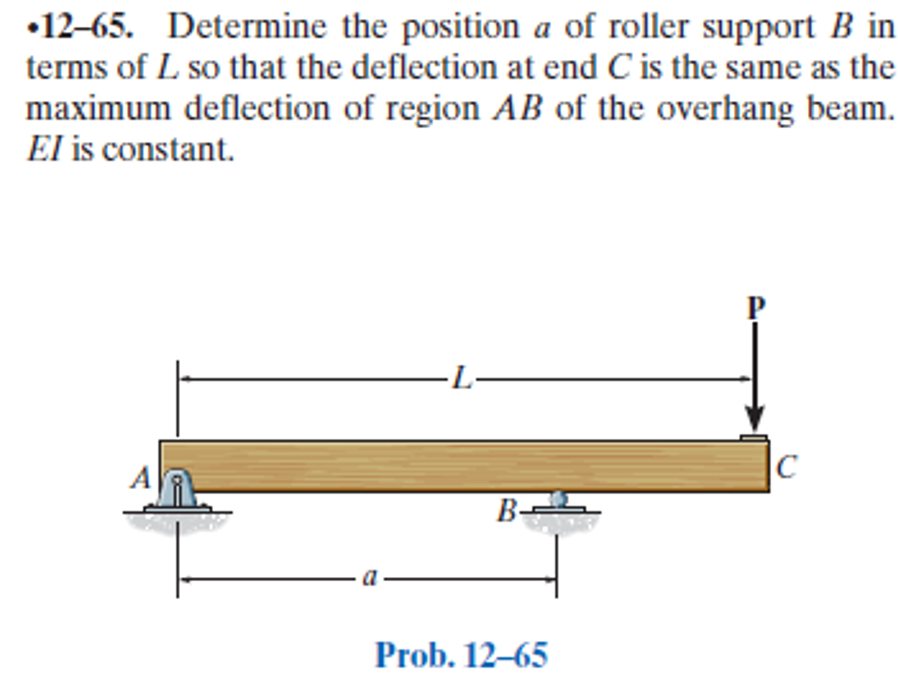

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-12-problem-65P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-12-problem-65P-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# load data

P = sym('P');
a = sym('a');
L = sym('L');
new_assum = 0 < a & a < L;
assume(new_assum);

# beam

b = beam;
b = b.add('reaction', 'force', 'Ra', 0);
b = b.add('reaction', 'force', 'Rb', a);
b = b.add('concentrated', 'force', -P, L);

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('factor');

# elastic curve

y

$$y(x) = \left\{ \begin{array}{cl} \frac{P\,x\,\left(a+x\right)\,\left(L-a\right)\,\left(a-x\right)}{6\,\text{E}\,\text{I}\,a} & \text{ if }x\leq a\\ -\frac{P\,\left(a-x\right)\,\left(L\,a-3\,L\,x+a\,x+x^{2}\right)}{6\,\text{E}\,\text{I}} & \text{ if }a<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} \frac{P\,\left(a^{2}-3\,x^{2}\right)\,\left(L-a\right)}{6\,\text{E}\,\text{I}\,a} & \text{ if }x\leq a\\ \frac{P\,\left(-a^{2}+4\,L\,a+3\,x^{2}-6\,L\,x\right)}{6\,\text{E}\,\text{I}} & \text{ if }a<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} -\frac{P\,x\,\left(L-a\right)}{a} & \text{ if }x\leq a\\ -P\,\left(L-x\right) & \text{ if }a<x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} -\frac{P\,\left(L-a\right)}{a} & \text{ if }x\leq a\\ P & \text{ if }a<x \end{array}\right.$$

w

$$w(x) = 0$$

# reactions and hinges

ra

$$ra = \left(\begin{array}{cc} \mathrm{Ra} & -\frac{P\,\left(L-a\right)}{a}\\ \mathrm{Rb} & \frac{L\,P}{a} \end{array}\right)$$

ha

 
ha =
 
Empty sym: 0-by-2
 


# shear and moment diagram

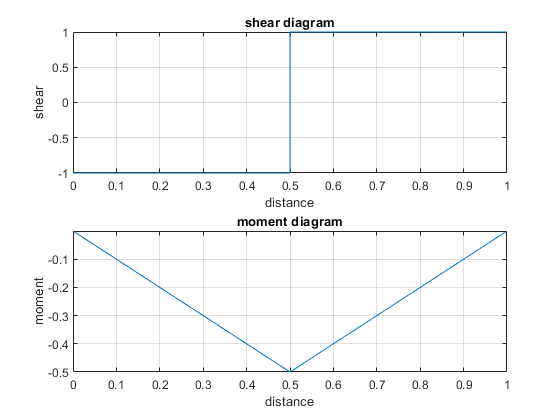

beam.shear_moment(m, v, [0 1], [P a L], [1 1/2 1]);

# maximum deflection of beam span AB

addvar(y);
assumeAlso(0 < x & x < a & E > 0 & I > 0 & L > 0);
xmax = solve(dy == 0)

$$xmax = \frac{\sqrt{3}\,a}{3}$$

ymax = simplify(y(xmax))

$$ymax = \frac{\sqrt{3}\,P\,a^{2}\,\left(L-a\right)}{27\,\text{E}\,\text{I}}$$

# solution of a

asol = solve(y(L) == -ymax, a, 'ReturnConditions', true);
asol = prodfactor(asol.a);
asol_vpa = vpa(asol, 3) %#ok<NASGU> 

$$asol\_vpa = 0.858\,L$$

# clean up

setassum(new_assum, 'clear');
clear asol_vpa;